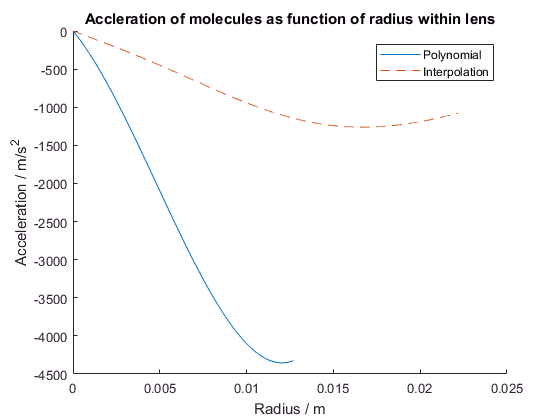

%% Plotting acceleration as function of radius to test my fitting based function
%by comparing to eqn (22) from Adam's ES lens write says the acceleration in his lens
%as function of r is 

d = .0254; %diameter of lens
r = linspace(0,d/2);
m = (204.38+19.00)*1.67e-27; %mass of TlF in kg

a = (-1.02e-19*r - 1.67e-17*r.^2 + 1.16e-15*r.^3)/m;

figure
hold on
plot(r,a)
plot(r_values,a_values,'--')
xlabel('Radius / m')
ylabel('Acceleration / m/s^2')
title('Accleration of molecules as function of radius within lens')
legend('Polynomial','Interpolation')

Calculate the spring constant from the analytic expression for the Stark shift

syms J m_J mu E h_bar B R V r h

W = mu^2*E^2/(2*h*B)*(J*(J+1) - 3*m_J^2)/(J*(J+1)*(2*J-1)*(2*J + 3))

$$W = \frac{{\text{E}}^{2}\,\mu^{2}\,\left(J\,\left(J+1\right)-3\,{m_{J}}^{2}\right)}{2\,B\,J\,h\,\left(2\,J-1\right)\,\left(2\,J+3\right)\,\left(J+1\right)}$$


E = 2*V*r/R^2

$$E = \frac{2\,V\,r}{R^{2}}$$


W = subs(W)

$$W = \frac{2\,V^{2}\,\mu^{2}\,r^{2}\,\left(J\,\left(J+1\right)-3\,{m_{J}}^{2}\right)}{B\,J\,R^{4}\,h\,\left(2\,J-1\right)\,\left(2\,J+3\right)\,\left(J+1\right)}$$



m = 3.7304e-25;       %Molecule mass in kg
h = 6.63e-34;         %Planck constant
h_bar = h/(2*pi);
J = 2                %Set J

J = 2

m_J = 0              %set m_Js

m_J = 0

V = 3e4              %Voltage

V = 30000

B = 6.68992e9;    %Rotational constant for TlF in Hz
mu = 4.2282 * 0.393430307 *5.291772e-9/4.135667e-15 * h * 1e-2 %[J/(V/m)]

mu = 1.4112e-29

R = 2.06e-2           %Radius of lens in meters

R = 0.0222


F = -diff(W,r)

$$F = -\frac{4\,V^{2}\,\mu^{2}\,r\,\left(J\,\left(J+1\right)-3\,{m_{J}}^{2}\right)}{B\,J\,R^{4}\,h\,\left(2\,J-1\right)\,\left(2\,J+3\right)\,\left(J+1\right)}$$


k = abs(double(coeffs(subs(F),r))) %in N/m

k = 3.1576e-20


k_a = k/m

k_a = 8.4645e+04

%Focal length calculations

L = .534; %length of lens
m = 3.7304e-25; %Mass of molecules
v_z = 200; %longitudinal velocity
p = sqrt(k/m)/v_z; %lens constant
d = (1-cos(p*L))./(p*sin(p*L)); %distance of principal plane from start of lens
f = 1/(p*sin(p*L)) %focal length

f = 0.9806

Calculate length of lens for a given source to lens distance such that the source is at the focal point of the lens. Do this graphically by plotting source to lens distance vs length of lens.

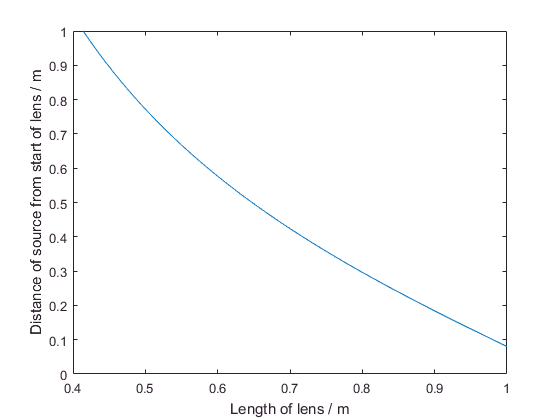

source_to_lens_distance = 0.805; %distance from beam source to start of lens
L = linspace(.1,1);
d = (1-cos(p*L))./(p*sin(p*L)); %distance of principal plane from start of lens
f = 1./(p*sin(p*L)); %focal length
lens_start = f-d;

figure
plot(L,lens_start)
xlabel('Length of lens / m')
ylabel('Distance of source from start of lens / m')
ylim([0:1])

Some plotting below to compare RK4 and Euler integration inside the lens

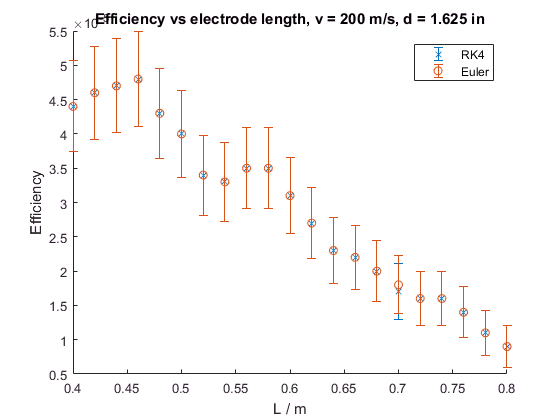

%Import the data for the RK4 run
filename = 'Data/loop_over_lens_length_06_20_2018_r=1.1625in_v=200_N=1e6_RK4';
delimiter = '\t';
header_lines = 1;
RK4_data = importdata(filename, delimiter, header_lines);

%Import data from Euler run
filename = 'Data/loop_over_lens_length_06_20_2018_r=1.1625in_v=200_N=1e6_Euler';
delimiter = '\t';
header_lines = 1;
Euler_data = importdata(filename, delimiter, header_lines);

figure
hold on
errorbar(RK4_data.data(:,1), RK4_data.data(:,4),RK4_data.data(:,5),'x')
title('Efficiency vs electrode length, v = 200 m/s, d = 1.625 in')
xlabel(RK4_data.colheaders(1))
ylabel(RK4_data.colheaders(4))

errorbar(Euler_data.data(:,1), Euler_data.data(:,4), Euler_data.data(:,5),'o')
legend('RK4','Euler')

Calculate dimensions of frame for given lens diameter

%Define radius of lens (everything in inches
r = 1.75/2; %radius

%Set distance along macor posts from lens to frame:
d = 2;

%Calculate height of frame:
h = 2*d + 2*(sqrt(2)+1)*r

h = 8.2249


%length of macor posts:
l_macor = .5+ d + .25

l_macor = 2.7500


%x-separation of macor slots on frame:
delta_x = sqrt(2)*2*r

delta_x = 2.4749